clear;
syms a positive
syms b nonzero
syms x1 x2

% find equilibrium points
f1 = -x1 + a*x2 - b*x1*x2 + x2^2;
f2 = -(a+b)*x1 + b*x1^2 - x1*x2;

sln = solve([f1==0, f2==0], [x1 x2]);
sln.x1

$$ans = \left(\begin{array}{c} 0\\ \frac{b^{2}+a\,b}{b^{2}+1}\\ 0 \end{array}\right)$$

sln.x2

$$ans = \left(\begin{array}{c} 0\\ -\frac{a+b}{b^{2}+1}\\ -a \end{array}\right)$$


% Jacobian
J = jacobian([f1 f2], [x1 x2])

$$J = \left(\begin{array}{cc} -b\,x_{2}-1 & a+2\,x_{2}-b\,x_{1}\\ 2\,b\,x_{1}-b-x_{2}-a & -x_{1} \end{array}\right)$$

for i=1:numel(sln.x1)
    disp('===============================')
    disp('Equilibrium Point: ')
    disp([sln.x1(i) sln.x2(i)])
    A = subs(J,[x1 x2], [sln.x1(i) sln.x2(i)]);
    disp('Eigenvalues: ')
    disp(eig(A))
end

Equilibrium Point: 


$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} -\frac{\sqrt{-4\,a^{2}-4\,b\,a+1}}{2}-\frac{1}{2}\\ \frac{\sqrt{-4\,a^{2}-4\,b\,a+1}}{2}-\frac{1}{2} \end{array}\right)$$

Equilibrium Point: 


$$\left(\begin{array}{cc} \frac{b^{2}+a\,b}{b^{2}+1} & -\frac{a+b}{b^{2}+1} \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} -\frac{\sqrt{-4\,b^{2}-4\,a\,b+1}}{2}-\frac{1}{2}\\ \frac{\sqrt{-4\,b^{2}-4\,a\,b+1}}{2}-\frac{1}{2} \end{array}\right)$$

Equilibrium Point: 


$$\left(\begin{array}{cc} 0 & -a \end{array}\right)$$

Eigenvalues: 


$$\left(\begin{array}{c} -1\\ a\,b \end{array}\right)$$

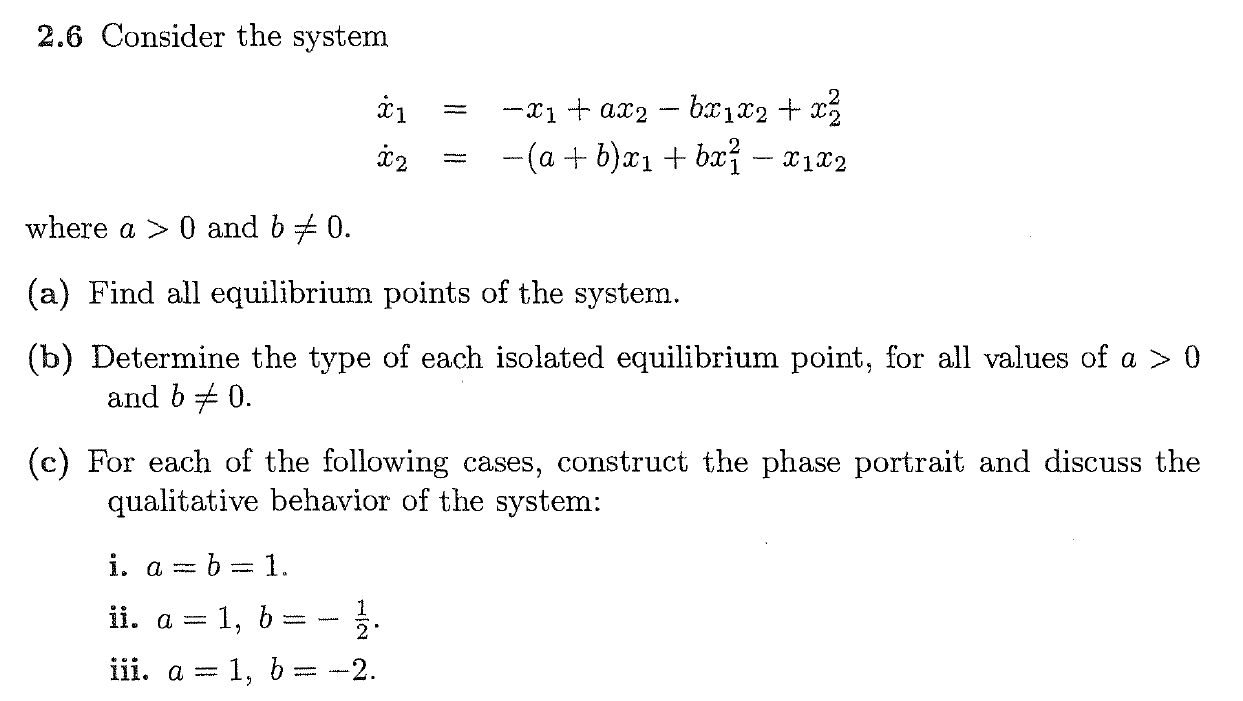

close all; clc

% Create vector field
x = linspace(-2,2,20); % vary as necessary
y = linspace(-2,2,20); % vary as necessary
[X,Y] = meshgrid(x,y);

aa = 1;
bb = -2; % change this value to 1 or -1/2
DX = -X + aa*Y - bb*X.*Y + Y.^2;             
DY = -(aa+bb)*X + bb*X.^2 - X.*Y;
quiver(X,Y,DX,DY,3);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title(strcat("Vector Field, a=", num2str(aa), ", b=", num2str(bb)))

hold on;
for i=1:numel(sln.x1)
    xx = subs(sln.x1(i), [a b], [aa bb]);
    yy = subs(sln.x1(i), [a b], [aa bb]);
    plot(xx, yy, 'rx')
    disp([xx yy])
end

$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cc} \frac{2}{5} & \frac{2}{5} \end{array}\right)$$

$$\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

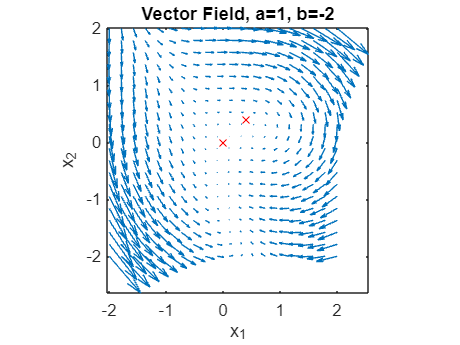

hold off